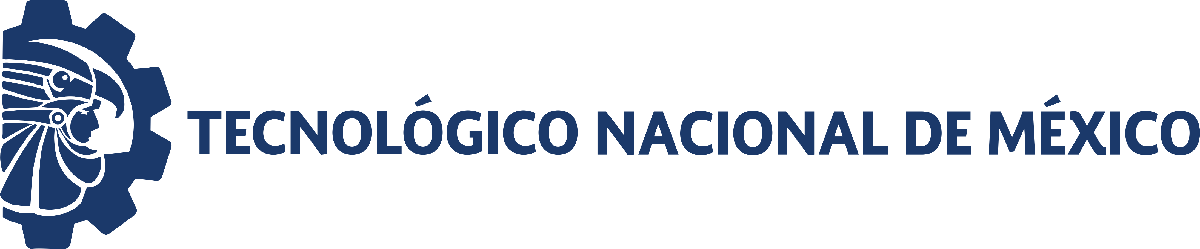                                 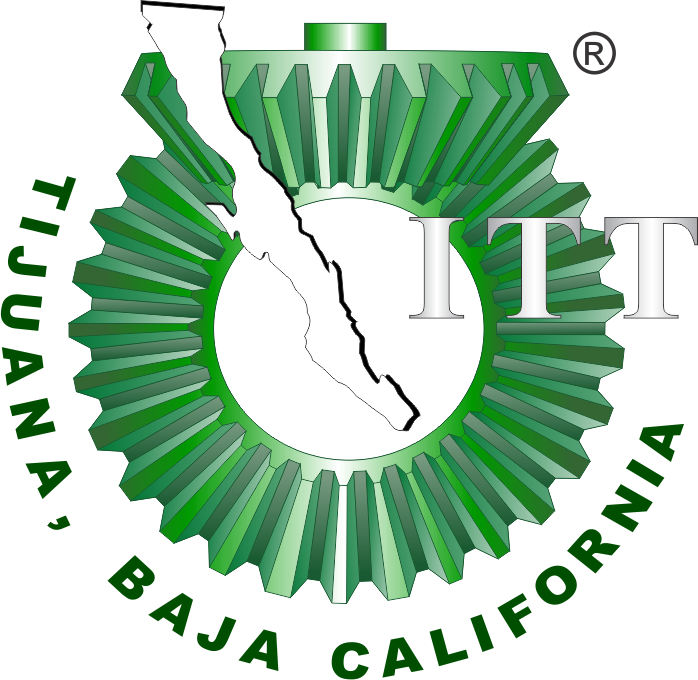

# Práctica 5: Análisis de sistemas biológicos

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

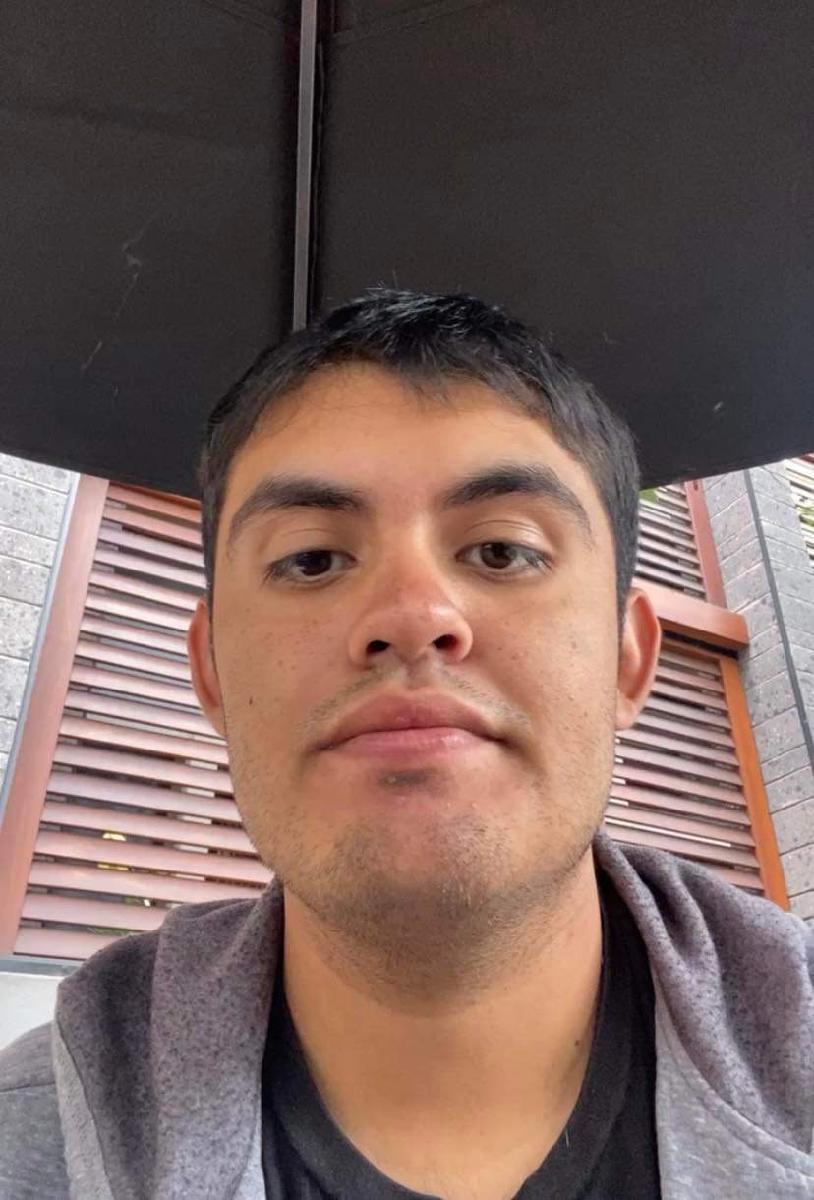

Nombre del alumno: **Andres Martin Bañuelos Elias**

Número de control: **21212142**

Correo institucional: **l21212142@tectijuana.edu.mx**

Carrera:** Ingenieria Biomedica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Simulation Data

## Chaotic Attractor [Normalized]

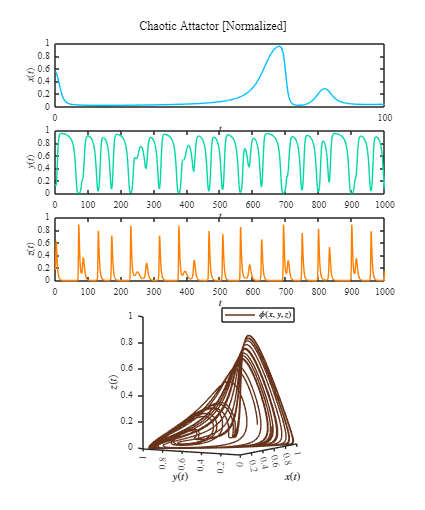

 clc; clear; close all; warning('off','all')
 r1 = 1; b1 = 1; a13 = 2.5; 
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
x0= 0.555;
y0 = 0.148;
z0 = 0.172;
a12 = 1;
tend= 1000;
P= [r1,b1,a13,r2,b2,a21,r3,a31,d3];
dt = 1E-2;
rhoi = 0;
[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs(t, x, y, z, 'Chaotic Attactor [Normalized]');
exportgraphics(gcf,'Chaotic Attractor.png','ContentType','vector')

## Periodic Orbit [Normalized]

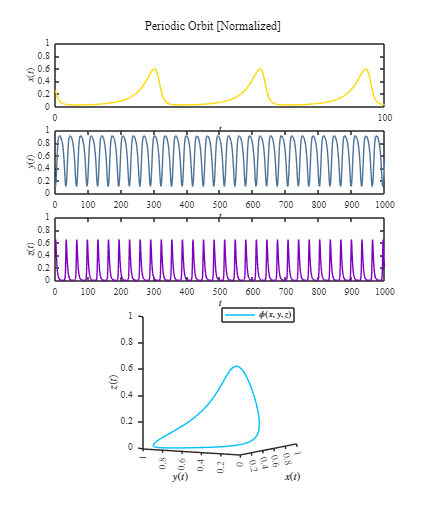

r1 = 1; b1 = 1; a13 = 2.5; 
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
x0= 0.254781;
y0 = 0.115167;
z0 = 0.600527;
a12 = 0.9;
tend= 1000;
P= [r1,b1,a13,r2,b2,a21,r3,a31,d3];
dt = 1E-2;
rhoi = 0;
[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs(t, x, y, z, 'Periodic Orbit [Normalized]');
exportgraphics(gcf,'Periodic Orbit.png','ContentType','vector')

## Internal Limit Cycle [Normalized]

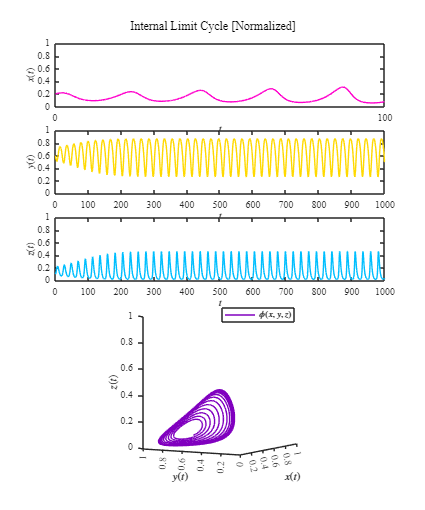

r1 = 1; b1 = 1; a13 = 2.5; 
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;

x0= 0.2;
y0 = 0.6;
z0 = 0.1;
a12 = 0.8;
tend= 1000;
P= [r1,b1,a13,r2,b2,a21,r3,a31,d3];
dt = 1E-2;
rhoi = 0;
[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs(t, x, y, z, 'Internal Limit Cycle [Normalized]');
 exportgraphics(gcf,'Internal Limit Cycle.png','ContentType','vector')

## External Limit Cycle [Normalized]

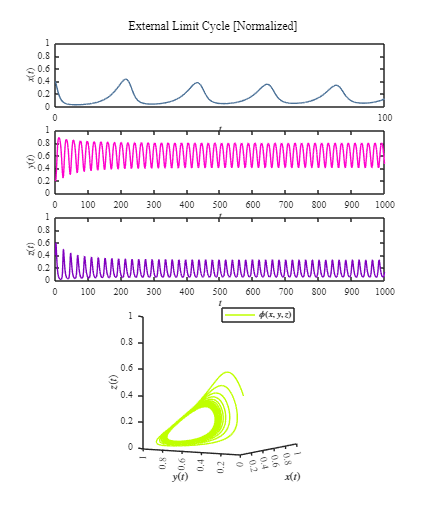

r1 = 1; b1 = 1; a13 = 2.5; 
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
x0= 0.4;
y0 = 0.2;
z0 = 0.4;
a12 = 0.75;
tend= 1000;
P= [r1,b1,a13,r2,b2,a21,r3,a31,d3];
dt = 1E-2;
rhoi = 0;
 [t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs(t, x, y, z, 'External Limit Cycle [Normalized]');
 exportgraphics(gcf,'External Limit Cycle.png','ContentType','vector')

## Convergence towards an equilibrium point [Normalized]

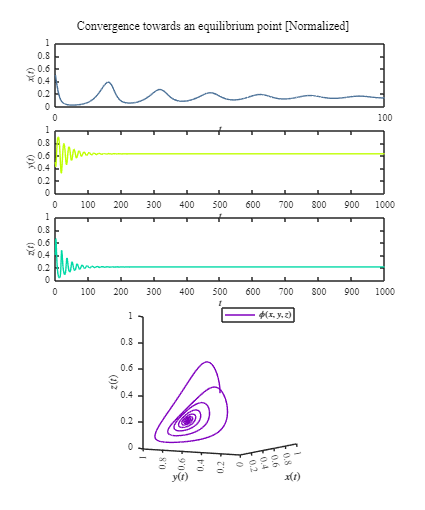

r1 = 1; b1 = 1; a13 = 2.5; 
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
x0= 0.5;
y0 = 0.5;
z0 = 0.4;
a12 = 0.5;
tend= 1000;
P= [r1,b1,a13,r2,b2,a21,r3,a31,d3];
dt = 1E-2;
rhoi = 0;
[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs(t, x, y, z, 'Convergence towards an equilibrium point [Normalized]');
 exportgraphics(gcf,'Convergence towards an equilibrium point.png','ContentType','vector')

## Chaotic Attractor [No normalized]

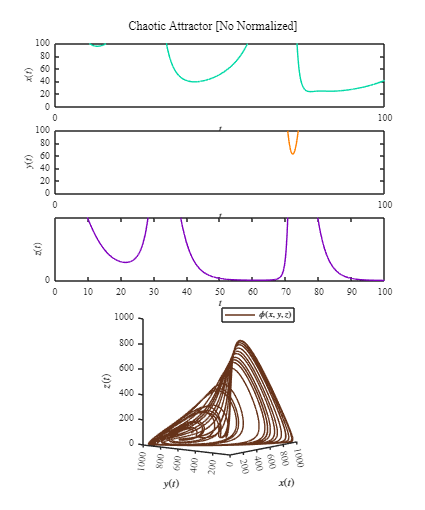

xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 1/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];
rhoi = 0;
x0 = 0.2*xmax; y0 = 0.6*ymax; z0 = 0.1*zmax;
dt = 1E-2; tend = 1000;
[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs2(t,x,y,z, 'Chaotic Attractor [No Normalized]');
exportgraphics(gcf,'Chaotic Attractor [No normalized].png','ContentType','vector')

## Convergence towards an equilibrium point [No normalized]

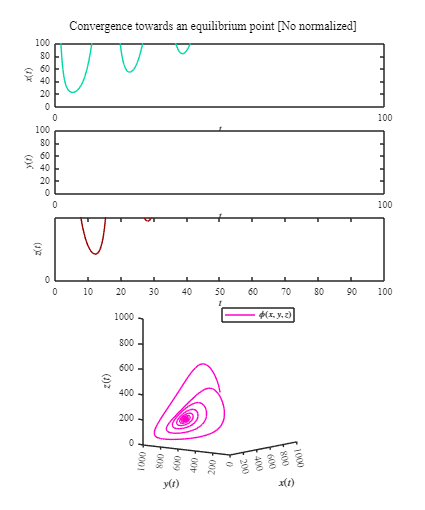

xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0.5/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];
rhoi = 0;
x0 = 0.5*xmax; y0 = 0.5*ymax; z0 = 0.4*zmax;
dt = 1E-2; tend = 1000;
[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs2(t,x,y,z, 'Convergence towards an equilibrium point [No normalized]');
exportgraphics(gcf,'Convergence towards an equilibrium point [No normalized].png','ContentType','vector')

## External Limit Cycle [No normalized]

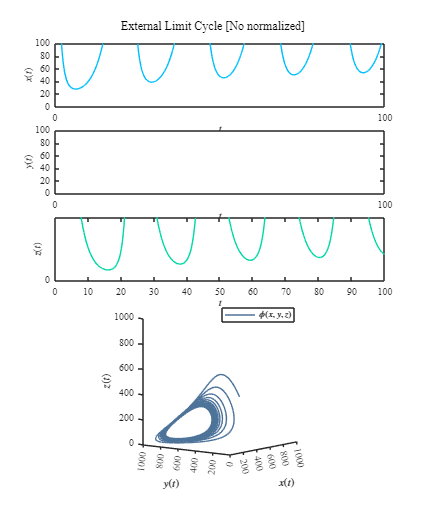

xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0.75/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];
rhoi = 0;
x0 = 0.4*xmax; y0 = 0.2*ymax; z0 = 0.4*zmax;
dt = 1E-2; tend = 1000;
[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs2(t,x,y,z, 'External Limit Cycle [No normalized]');
exportgraphics(gcf,'External Limit Cycle [No normalized].png','ContentType','vector')

## Internal Limit Cycle [No Normalized]

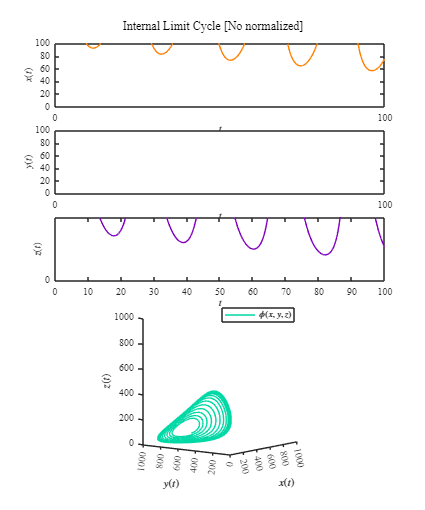

xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0.8/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];
rhoi = 0;
x0 = 0.2*xmax; y0 = 0.6*ymax; z0 = 0.1*zmax;
dt = 1E-2; tend = 1000;
[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs2(t,x,y,z, 'Internal Limit Cycle [No normalized]');
exportgraphics(gcf,'Internal Limit Cycle [No normalized].png','ContentType','vector')

## Periodic Orbit [No Normalized]

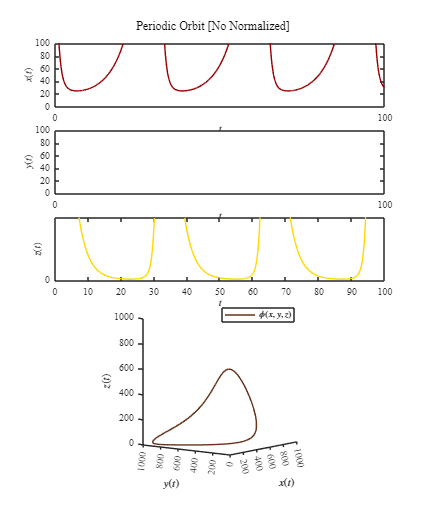

xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0.9/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];
rhoi = 0;
x0 = 0.254781*xmax; y0 = 0.115167*ymax; z0 = 0.600527*zmax;
dt = 1E-2; tend = 1000;
[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs2(t,x,y,z, 'Periodic Orbit [No Normalized]');
exportgraphics(gcf,'Periodic Orbit [No normalized].png','ContentType','vector')

## **Comparison of Non-Normalized Dynamics for Cancer Modeling**

The best non-normalized simulation to describe cancer is the one that presents a **chaotic attractor**, as it:

represents unpredictable dynamic behaviors, which is consistent with the nonlinear and heterogeneous progression of many types of cancer.

However, the option of a **system with an internal limit cycle**:

- represents a sustained and bounded oscillation—that is, the system neither diverges (as in chaos) nor collapses (as in convergence)—making it useful for modeling latent tumors, cyclic immune responses, or periodic treatments.

- The trajectories remain within an internal region of the phase space, which biologically simulates systems that self-regulate without completely eradicating or allowing the tumor to grow uncontrollably.

- It is ideal for studies involving coexistence or dynamic equilibrium between cancer, the immune system, and a therapy.

**Comparación de Dinámicas No Normalizadas para la Modelización del Cáncer**

La mejor simulación no normalizada para describir el cáncer es la que presenta un **atractor caótico**, ya que;

Representa comportamientos dinámicos impredecibles, lo cual es coherente con la progresión no lineal y heterogénea de muchas formas de cáncer.

Sin embargo, la opción de un sistema de **ciclo límite interno**:

- Representa una oscilación sostenida y contenida, es decir, el sistema no diverge (como en el caos) ni colapsa (como en la convergencia), lo cual es útil para modelar tumores latentes, respuestas inmunes cíclicas o tratamientos periódicos.

- Las trayectorias se mantienen en una región interna del espacio de fases, lo que simula biológicamente sistemas que se autorregulan sin erradicar ni dejar crecer el tumor indefinidamente.

- Es ideal para estudios donde hay coexistencia o equilibrio dinámico entre el cáncer, el sistema inmune y una terapia.

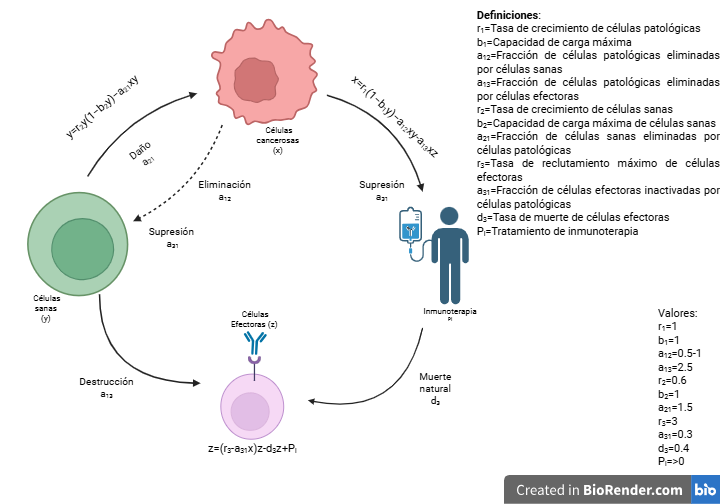

El diagrama representa un modelo mecanicista basado en ecuaciones diferenciales ordinarias (EDOs) que describe la dinámica entre tres poblaciones celulares: células cancerosas (x), células sanas (y) y células efectoras del sistema inmune (z), incorporando también el efecto de un tratamiento de inmunoterapia Pi.

## Equilibrium points and Jacobian Matrix

clear
syms x y z r1 b1 a12 a13 r2 b2 a21 r3 a31 d3 rho1

dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z;
dy = r2*y*(1 - b2*y) - a12*x*y;
dz = (r3 - a31)*x*z - d3*z + rho1;
J = jacobian([dx,dy,dz],[x,y,z]); disp(J)

$$\left(\begin{array}{ccc} -a_{12}\,y-a_{13}\,z-r_{1}\,\left(b_{1}\,x-1\right)-b_{1}\,r_{1}\,x & -a_{12}\,x & -a_{13}\,x\\ -a_{12}\,y & -a_{12}\,x-r_{2}\,\left(b_{2}\,y-1\right)-b_{2}\,r_{2}\,y & 0\\ -z\,\left(a_{31}-r_{3}\right) & 0 & -d_{3}-x\,\left(a_{31}-r_{3}\right) \end{array}\right)$$


dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z== 0;
dy = r2*y*(1 - b2*y) - a12*x*y == 0;
dz = (r3 - a31)*x*z - d3*z + rho1 == 0;
equilibria = solve([dx,dy,dz],[x,y,z]);

for i = 1:6
  xe(i,1) = simplify(equilibria.x(i));
  ye(i,1) = simplify(equilibria.y(i));
  ze(i,1) = simplify(equilibria.z(i));

    disp(['Equilibrium points of the system: ', num2str(i)])
    disp(['x', num2str(i), ' = ', char(xe(i,1))]);
    disp(['y', num2str(i), ' = ', char(ye(i,1))]);
    disp(['z', num2str(i), ' = ', char(ze(i,1))]);
end

Equilibrium points of the system: 1


x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3))


y1 = 0


z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3))


Equilibrium points of the system: 2


x2 = -(a12^2*d3 + (a12^4*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + 2*a12^3*a31*d3*r2 - 2*a12^3*d3*r2*r3 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 4*a12^2*a13*a31*b2*r2*rho1 - 2*a12^2*a31*b2*d3*r1*r2 + 4*a12*a31*b2*r1*r2^2*r3 - 4*a12^2*a13*b2*r2*r3*rho1 + 2*a12^2*b2*d3*r1*r2*r3 - 2*a12^2*b1*b2*d3^2*r1*r2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12^2 - b1*b2*r1*r2)*(a31 - r3))


y2 = (a12*(a12^4*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + 2*a12^3*a31*d3*r2 - 2*a12^3*d3*r2*r3 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 4*a12^2*a13*a31*b2*r2*rho1 - 2*a12^2*a31*b2*d3*r1*r2 + 4*a12*a31*b2*r1*r2^2*r3 - 4*a12^2*a13*b2*r2*r3*rho1 + 2*a12^2*b2*d3*r1*r2*r3 - 2*a12^2*b1*b2*d3^2*r1*r2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12^3*d3 - a12^2*r2*r3 + a12^2*a31*r2 + a12*a31*b2*r1*r2 - a12*b2*r1*r2*r3 - 2*a31*b1*b2*r1*r2^2 + 2*b1*b2*r1*r2^2*r3 - a12*b1*b2*d3*r1*r2)/(2*b2*r2*(a12^2 - b1*b2*r1*r2)*(a31 - r3))


z2 = -(a12^2*d3 + (a12^4*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + 2*a12^3*a31*d3*r2 - 2*a12^3*d3*r2*r3 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 4*a12^2*a13*a31*b2*r2*rho1 - 2*a12^2*a31*b2*d3*r1*r2 + 4*a12*a31*b2*r1*r2^2*r3 - 4*a12^2*a13*b2*r2*r3*rho1 + 2*a12^2*b2*d3*r1*r2*r3 - 2*a12^2*b1*b2*d3^2*r1*r2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))


Equilibrium points of the system: 3


x3 = ((a12^4*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + 2*a12^3*a31*d3*r2 - 2*a12^3*d3*r2*r3 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 4*a12^2*a13*a31*b2*r2*rho1 - 2*a12^2*a31*b2*d3*r1*r2 + 4*a12*a31*b2*r1*r2^2*r3 - 4*a12^2*a13*b2*r2*r3*rho1 + 2*a12^2*b2*d3*r1*r2*r3 - 2*a12^2*b1*b2*d3^2*r1*r2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12^2*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12^2 - b1*b2*r1*r2)*(a31 - r3))


y3 = -(a12*(a12^4*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + 2*a12^3*a31*d3*r2 - 2*a12^3*d3*r2*r3 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 4*a12^2*a13*a31*b2*r2*rho1 - 2*a12^2*a31*b2*d3*r1*r2 + 4*a12*a31*b2*r1*r2^2*r3 - 4*a12^2*a13*b2*r2*r3*rho1 + 2*a12^2*b2*d3*r1*r2*r3 - 2*a12^2*b1*b2*d3^2*r1*r2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12^3*d3 + a12^2*r2*r3 - a12^2*a31*r2 - a12*a31*b2*r1*r2 + a12*b2*r1*r2*r3 + 2*a31*b1*b2*r1*r2^2 - 2*b1*b2*r1*r2^2*r3 + a12*b1*b2*d3*r1*r2)/(2*b2*r2*(a12^2 - b1*b2*r1*r2)*(a31 - r3))


z3 = ((a12^4*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + 2*a12^3*a31*d3*r2 - 2*a12^3*d3*r2*r3 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 4*a12^2*a13*a31*b2*r2*rho1 - 2*a12^2*a31*b2*d3*r1*r2 + 4*a12*a31*b2*r1*r2^2*r3 - 4*a12^2*a13*b2*r2*r3*rho1 + 2*a12^2*b2*d3*r1*r2*r3 - 2*a12^2*b1*b2*d3^2*r1*r2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12^2*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))


Equilibrium points of the system: 4


x4 = 0


y4 = 1/b2


z4 = rho1/d3


Equilibrium points of the system: 5


x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3))


y5 = 0


z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3))


Equilibrium points of the system: 6


x6 = 0


y6 = 0


z6 = rho1/d3


## Equilibrium points

clear
a12i = [1;0.9;0.8;0.75;0.5]

a12i =     1.0000
    0.9000
    0.8000
    0.7500
    0.5000


r1 = 1; b1 = 1; a12 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
rhoi = 0;
for i = 1:numel(a12i)
    a12 = a12i(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rhoi/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rhoi/d3;

    xe = [x1; x2; x3; x4; x5; x6]; ye = [y1; y2; y3; y4; y5; y6]; ze = [z1; z2; z3; z4; z5; z6];

    Eqs = array2table([xe, ye, ze], 'VariableNames', {'x*','y*','z*'});
    fprintf(['Equilibrium points with a12 = ',num2str(a12), '\n'])
    fprintf(['Treatment rhoi = ', num2str(rhoi), '\n'])
    disp(Eqs)
end

Equilibrium points with a12 = 1


Treatment rhoi = 0


        x*           y*           z*     
    ___________    _______    ___________

        0.14815          0        0.34074
        0.14815    0.62963       0.088889
    -4.5688e-17          1    -5.4826e-17
              0          1              0
              1          0     2.4672e-17
              0          0              0



Equilibrium points with a12 = 0.9


Treatment rhoi = 0


      x*         y*           z*     
    _______    _______    ___________

    0.14815          0        0.34074
    0.14815    0.62963        0.11407
      -0.08        1.2    -5.4826e-17
          0          1              0
          1          0     2.4672e-17
          0          0              0



Equilibrium points with a12 = 0.8


Treatment rhoi = 0


      x*         y*           z*     
    _______    _______    ___________

    0.14815          0        0.34074
    0.14815    0.62963        0.13926
       -0.2        1.5    -1.3706e-16
          0          1              0
          1          0     2.4672e-17
          0          0              0



Equilibrium points with a12 = 0.75


Treatment rhoi = 0


       x*         y*           z*    
    ________    _______    __________

     0.14815          0       0.34074
     0.14815    0.62963       0.15185
    -0.28571     1.7143    1.3706e-16
           0          1             0
           1          0    2.4672e-17
           0          0             0



Equilibrium points with a12 = 0.5


Treatment rhoi = 0


      x*         y*           z*    
    _______    _______    __________

    0.14815          0       0.34074
    0.14815    0.62963       0.21481
         -2          6             0
          0          1             0
          1          0    2.4672e-17
          0          0             0



## Equilibrium points with treament

clear
a12l = [1; 0.9; 0.8; 0.75; 0.5];

r1 = 1; b1 = 1; a12 = 1; a13 = 2.5;
r2 = 1; b2 = 4; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
rho1 = 1.1*(d3*r1)/a13;

for i = 1:numel(a12l)
    a12 = a12l(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rho1/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rho1/d3;

      xe = [x1; x2; x3; x4; x5; x6]; 
    ye = [y1; y2; y3; y4; y5; y6]; 
    ze = [z1; z2; z3; z4; z5; z6];

    Eqs = array2table([xe, ye, ze], 'VariableNames', {'x*','y*','z*'});
    fprintf(['Equilibrium points with a12 = ', num2str(a12), '\n'])
    fprintf(['Treatment rho1 = ', num2str(rho1), '\n'])
    disp(Eqs)
end

Equilibrium points with a12 = 1


Treatment rho1 = 0.176


       x*           y*          z*    
    _________    ________    _________

    -0.012761           0       0.4051
     -0.05896     0.27211      0.31474
       1.4071    -0.27767    -0.051777
            0        0.25         0.44
       1.1609           0    -0.064364
            0           0         0.44



Equilibrium points with a12 = 0.9


Treatment rho1 = 0.176


       x*           y*          z*    
    _________    ________    _________

    -0.012761           0       0.4051
    -0.053011     0.26988      0.32405
        1.371    -0.26411    -0.053307
            0        0.25         0.44
       1.1609           0    -0.064364
            0           0         0.44



Equilibrium points with a12 = 0.8


Treatment rho1 = 0.176


       x*           y*          z*    
    _________    ________    _________

    -0.012761           0       0.4051
    -0.047437     0.26779      0.33328
       1.3384    -0.25192    -0.054764
            0        0.25         0.44
       1.1609           0    -0.064364
            0           0         0.44



Equilibrium points with a12 = 0.75


Treatment rho1 = 0.176


       x*           y*          z*    
    _________    ________    _________

    -0.012761           0       0.4051
    -0.044779     0.26679      0.33787
       1.3234    -0.24626    -0.055467
            0        0.25         0.44
       1.1609           0    -0.064364
            0           0         0.44



Equilibrium points with a12 = 0.5


Treatment rho1 = 0.176


       x*           y*          z*    
    _________    ________    _________

    -0.012761           0       0.4051
     -0.03262     0.26223       0.3606
       1.2577    -0.22163     -0.05875
            0        0.25         0.44
       1.1609           0    -0.064364
            0           0         0.44



## Internal Limit Cycle [Not Normalized]-No Treatment

%%

clear
xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0.8/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;

rho1 = 0;

for i = 1:numel(a12)
    a12 = a12(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rho1/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rho1/d3;

      xe = [x1; x2; x3; x4; x5; x6]; 
    ye = [y1; y2; y3; y4; y5; y6]; 
    ze = [z1; z2; z3; z4; z5; z6];

  x = [x1; x2; x3; x4; x5; x6];
y = [y1; y2; y3; y4; y5; y6];
z = [z1; z2; z3; z4; z5; z6];

fprintf(['Equilibrium points with a12 = ', num2str(a12), '\n'])
fprintf(['Treatment rho1 = ', num2str(rho1), '\n'])

for j = 1:numel(x)
    J = [
        -a12*y(j) - a13*z(j) - r1*(b1*x(j) - 1) - b1*r1*x(j),   -a12*x(j),             -a13*x(j);
        -a21*y(j),                                             -a21*x(j) - r2*(b2*y(j) - 1) - b2*r2*y(j),   0;
        -z(j)*(a31 - r3),                                      0,                     -d3*x(j)*(a31 - r3)
    ];
    L(j,:) = eig(J);
end

Lambda1 = L(:,1);
Lambda2 = L(:,2);
Lambda3 = L(:,3);

Results = table(x, y, z, Lambda1, Lambda2, Lambda3);
disp(Results)

end

Equilibrium points with a12 = 0.0008


Treatment rho1 = 0


      x         y           z              Lambda1               Lambda2               Lambda3     
    ______    ______    __________    __________________    __________________    _________________

    148.15         0        340.74    0.0059259+0.56303i    0.0059259-0.56303i     0.37778+0i      
    148.15    629.63        139.26     -0.56222+0i           0.098145+0.31602i    0.098145-0.31602i
      -200      1500    3.2679e-14        -0.35+0.23979i        -0.35-0.23979i      -0.216+0i      
         0      1000             0         -0.6+0i                0.2+0i                 0+0i      
      1000         0    1.2047e-14           -1+0i               1.08+0i              -0.9+0i      
         0         0             0            0+0i                0.6+0i                 1+0i  

## Internal Limit Cycle [Not Normalized]-with treatment

clear
xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0.8/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;

rho1 = 1.1*(d3*r1)/a13

rho1 = 176.0000


for i = 1:numel(a12)
    a12 = a12(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rho1/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rho1/d3;

      xe = [x1; x2; x3; x4; x5; x6]; 
    ye = [y1; y2; y3; y4; y5; y6]; 
    ze = [z1; z2; z3; z4; z5; z6];

  x = [x1; x2; x3; x4; x5; x6];
y = [y1; y2; y3; y4; y5; y6];
z = [z1; z2; z3; z4; z5; z6];

fprintf(['Equilibrium points with a12 = ', num2str(a12), '\n'])
fprintf(['Treatment rho1 = ', num2str(rho1), '\n'])

for j = 1:numel(x)
    J = [
        -a12*y(j) - a13*z(j) - r1*(b1*x(j) - 1) - b1*r1*x(j),   -a12*x(j),             -a13*x(j);
        -a21*y(j),                                             -a21*x(j) - r2*(b2*y(j) - 1) - b2*r2*y(j),   0;
        -z(j)*(a31 - r3),                                      0,                     -d3*x(j)*(a31 - r3)
    ];
    L(j,:) = eig(J);
end

Lambda1 = L(:,1);
Lambda2 = L(:,2);
Lambda3 = L(:,3);

Results = table(x, y, z, Lambda1, Lambda2, Lambda3);
disp(Results)

end

Equilibrium points with a12 = 0.0008


Treatment rho1 = 176


           x                 y                  z                Lambda1              Lambda2               Lambda3     
    _______________    ______________    _______________    _________________    __________________    _________________

    -12.761+0i              0+0i           405.1+0i         0.18676+0i           -0.18778+0i            0.61914+0i      
    -25.926+364.23i    1064.8-910.57i      69.63+145.69i    -1.0496-0.069563i     0.67265+0.080957i    -0.26403+0.56408i
    -25.926-364.23i    1064.8+910.57i      69.63-145.69i    -1.0496+0.069563i     0.67265-0.080957i    -0.26403-0.56408i
          0+0i           1000+0i             440+0i               0+0i               -0.6+0i               -0.9+0i      
     1160.9+0i              0+0i         -64.364+0i         -1.3543+0

## Internal Limit Cycle [No Normalized]

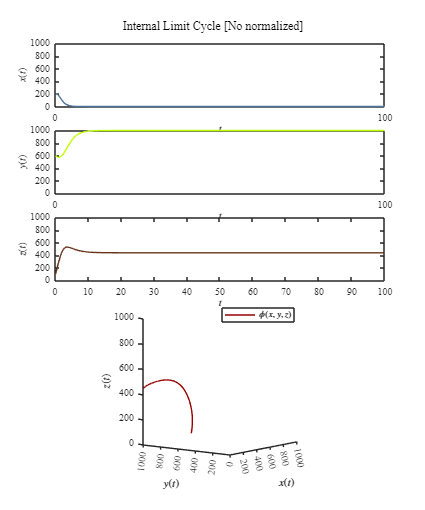

xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0.8/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];
rho1 = 1.1*(d3*r1)/a13;
x0 = 0.2*xmax; y0 = 0.6*ymax; z0 = 0.1*zmax;
dt = 1E-2; tend = 1000;
[t,x,y,z] = system(x0,y0,z0,P,a12,rho1,dt,tend);
plotEDOs2(t,x,y,z, 'Internal Limit Cycle [No normalized]');
exportgraphics(gcf,'Internal Limit Cycle [No normalized].png','ContentType','vector')

## Functions

## Chaotic system function

function [t, x, y, z] = system(x0, y0, z0, P, a12, rhoi, dt, tend)
    r1 = P(1); b1 = P(2); a13 = P(3);
    r2 = P(4); b2 = P(5); a21 = P(6);
    r3 = P(7); a31 = P(8); d3 = P(9);

    t = (0:dt:tend)';
    n = round(tend/dt);

    x = zeros(n+1, 1); x(1) = x0;
    y = zeros(n+1, 1); y(1) = y0;
    z = zeros(n+1, 1); z(1) = z0;

    for i = 1:n
        [fx, fy, fz] = f(x(i), y(i), z(i));
        xn = x(i) + fx * dt;
        yn = y(i) + fy * dt;
        zn = z(i) + fz * dt;
        [fxn, fyn, fzn] = f(xn, yn, zn);

        x(i+1) = x(i) + (fx + fxn) * dt / 2;
        y(i+1) = y(i) + (fy + fyn) * dt / 2;
        z(i+1) = z(i) + (fz + fzn) * dt / 2;
    end

    function [dx, dy, dz] = f(x, y, z)
        dx = r1 * x * (1 - b1 * x) - a12 * x * y - a13 * x * z;
        dy = r2 * y * (1 - b2 * y) - a21 * x * y;
        dz = (r3 - a31) * x * z - d3 * z + rhoi;
    end
end

## Solutions and trajectories

function plotEDOs(t, x, y, z, titleText)
    set(figure(), 'Color', 'w')
    set(gcf, 'Units', 'Centimeters', 'Position', [1, 1, 15, 18])
    
    Mecambiareaindustrial = [
        0.60, 0.00, 0.00;  
        0.75, 1.00, 0.00;  
        0.00, 0.75, 1.00;  
        0.50, 0.00, 0.75;
        1.00, 0.50, 0.00;  
        0.40, 0.20, 0.10;  
        1.00, 0.00, 0.80;  
        1.00, 0.85, 0.00; 
        0.00, 0.85, 0.65;  
        0.30, 0.45, 0.60   
    ];    
    rng('shuffle'); 
    indices = randperm(size(Mecambiareaindustrial, 1), 4); 
    c1 = Mecambiareaindustrial(indices(1), :);
    c2 = Mecambiareaindustrial(indices(2), :);
    c3 = Mecambiareaindustrial(indices(3), :);
    c4 = Mecambiareaindustrial(indices(4), :);  

    % Subplot x(t)
    subplot(5, 4, 1:4);
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points');
    hold on; box on; grid off;
    plot(t, x, '-', 'LineWidth', 1, 'Color', c1)
    xlabel('$t$', 'Interpreter', 'Latex')
    ylabel('$x(t)$', 'Interpreter', 'Latex')
    xlim([0 100]); xticks(0:100:1000)
    ylim([0 1]); yticks(0:0.2:1)

    % Subplot y(t)
    subplot(5, 4, 5:8);
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points');
    hold on; box on; grid off;
    plot(t, y, '-', 'LineWidth', 1, 'Color', c2)
    xlabel('$t$', 'Interpreter', 'Latex')
    ylabel('$y(t)$', 'Interpreter', 'Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1]); yticks(0:0.2:1)

    % Subplot z(t)
    subplot(5, 4, 9:12);
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points');
    hold on; box on; grid off;
    plot(t, z, '-', 'LineWidth', 1, 'Color', c3)
    xlabel('$t$', 'Interpreter', 'Latex')
    ylabel('$z(t)$', 'Interpreter', 'Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1]); yticks(0:0.2:1)

    % Subplot 3D
    subplot(5, 4, [14, 15, 18, 19]);
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points');
    hold on; box off; grid off;
    plot3(x, y, z, '-', 'LineWidth', 0.5, 'Color', c4)
    set(gca, 'XDir', 'reverse');
    set(gca, 'YDir', 'reverse');
    xlabel('$x(t)$', 'Interpreter', 'Latex');
    ylabel('$y(t)$', 'Interpreter', 'Latex');
    zlabel('$z(t)$', 'Interpreter', 'Latex');
    xlim([0 1]); ylim([0 1]); zlim([0 1]);
    xticks(0.2:0.2:1); yticks(0:0.2:1); zticks(0:0.2:1);
    L = legend('$\phi(x,y,z)$');
    set(L, 'Interpreter', 'Latex', 'Location', 'Best', 'Box', 'On')
    view(120.2, 5.5);
    sgtitle(titleText, 'FontName', 'Times New Roman', 'FontSize', 12)
end


## Solutions and trajectories [No normalized]

function plotEDOs2(t,x,y,z,titleText)
    figure('Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,15,18])

    Mecambiareaindustrial = [
        0.60, 0.00, 0.00;  
        0.75, 1.00, 0.00;  
        0.00, 0.75, 1.00;  
        0.50, 0.00, 0.75;
        1.00, 0.50, 0.00;  
        0.40, 0.20, 0.10;  
        1.00, 0.00, 0.80;  
        1.00, 0.85, 0.00; 
        0.00, 0.85, 0.65;  
        0.30, 0.45, 0.60   
    ];    

    rng('shuffle'); 
    indices = randperm(size(Mecambiareaindustrial,1), 4); 
    c1 = Mecambiareaindustrial(indices(1), :);
    c2 = Mecambiareaindustrial(indices(2), :);
    c3 = Mecambiareaindustrial(indices(3), :);
    c4 = Mecambiareaindustrial(indices(4), :);

    subplot(5, 4, 1:4);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color', c1)
    xlabel('$t$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:100:100)
    ylim([0 1E3]); yticks(0:0.2E3:1E3)

    subplot(5, 4, 5:8);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1, 'Color', c2)
    xlabel('$t$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:100:100)
    ylim([0 1E3]); yticks(0:0.2E3:1E3)

    subplot(5, 4, 9:12);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,z,'-','LineWidth',1,'Color', c3)
    xlabel('$t$','Interpreter','Latex')
    ylabel('$z(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 1E3]); yticks(0:0.2E3:1E3)

    subplot(5, 4, [14, 15, 18, 19]);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box off; grid off;
    plot3(x, y, z, '-', 'LineWidth', 0.5,'Color', c4)
    set(gca, 'XDir', 'reverse');
    set(gca, 'YDir', 'reverse');
    xlabel('$x(t)$', 'Interpreter', 'Latex');
    ylabel('$y(t)$', 'Interpreter', 'Latex');
    zlabel('$z(t)$', 'Interpreter', 'Latex');
    view(127.5, 7.5);
    xlim([0 1E3]); ylim([0 1E3]); zlim([0 1E3]);
    xticks(0.2E3:0.2E3:1E3); yticks(0:0.2E3:1E3); zticks(0:0.2E3:1E3);
    L = legend('$\phi(x,y,z)$');
    set(L,'Interpreter','Latex','Location','Best','Box','On')

    sgtitle(titleText, 'FontName', 'Times New Roman', 'FontSize', 12)
end
